clear 
s = settings;
s.matlab.appearance.figure.GraphicsTheme.TemporaryValue = "light";
load("C:\Users\Steven Watts\OneDrive - Stellenbosch University\Uni\Masters\Results\3_Legged.mat")

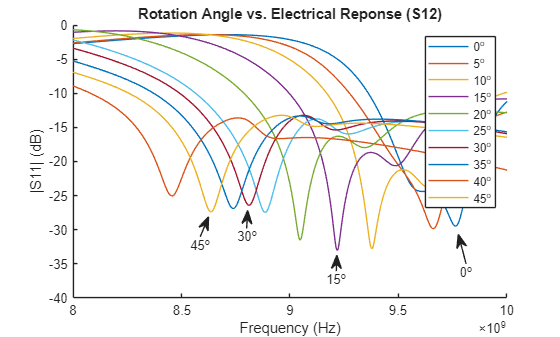

figure 
hold on
for ii = 1: 10%size(dataStack,1)

    rotAng = 5 * (ii-1);
    sol = dataStack(ii,"Solution");
    SP = squeeze(cell2mat(sol.Solution).S(1,2,:,1));
    freq = cell2mat(sol.Solution).Freq;
    plot(freq,20*log10(abs(SP)),DisplayName=[num2str(rotAng) '^o'])

end
xlim([8e9,10e9])
ylim([-40,0])
title('Rotation Angle vs. Electrical Reponse (S12)')
ylabel('|S11| (dB)')
xlabel('Frequency (Hz)')
legend
annotation("textarrow", [0.8324 0.8184], [0.2169 0.3045], "String", "0^o")
annotation("textarrow", [0.6006 0.6015], [0.1953 0.2427], "String", "15^o")
annotation("textarrow", [0.4404 0.4423], [0.322 0.3756], "String", "30^o")
annotation("textarrow", [0.3575 0.3724], [0.2974 0.3569], "String", "45^o")

hold off

saveas(gcf,'C:\Users\Steven Watts\OneDrive - Stellenbosch University\Steven\Papers\Paper 1\Data Acquisition\RotAng Vs S12.png')


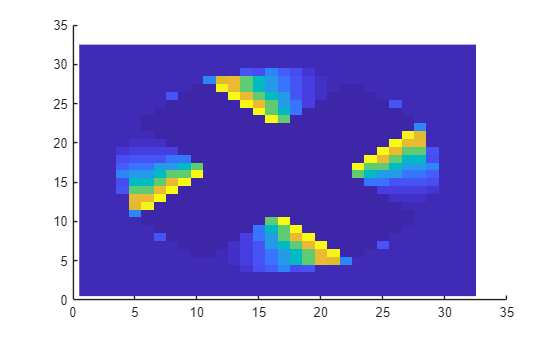

top = cell2mat(dataStack.Grid(10));
figure 
hold on 
for ii = 9: -1: 1%size(dataStack,1)

    shape = ~cell2mat(dataStack.Grid(ii));
    
    top = top + ii  * (top>0 & shape);

end

    %imagesc(cell2mat(dataStack.Grid(ii)));
    imagesc(top);

hold off

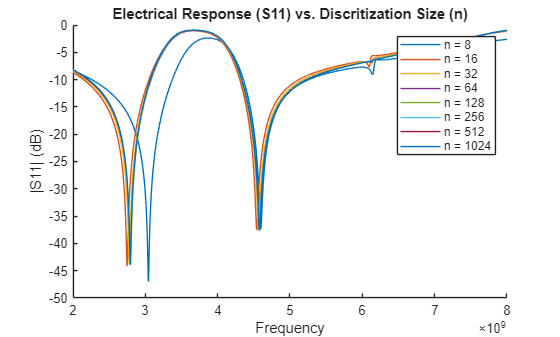

clear 
s = settings;
s.matlab.appearance.figure.GraphicsTheme.TemporaryValue = "light";
load("C:\Users\Steven Watts\OneDrive - Stellenbosch University\Uni\Masters\Results\New Folder\n_Trial.mat")

figure 
hold on
for ii = 1: size(dataStack,1)
    n = dataStack.n(ii);
    sol = dataStack(ii,"Solution");
    SP = squeeze(cell2mat(sol.Solution).S(1,2,:,1));
    freq = cell2mat(sol.Solution).Freq;
    plot(freq,20*log10(abs(SP)),DisplayName=['n = ' num2str(n)])

end
hold off
legend
title('Electrical Response (S11) vs. Discritization Size (n)')
xlabel('Frequency (Hz)')
ylabel('|S11| (dB)')

saveas(gcf,'C:\Users\Steven Watts\OneDrive - Stellenbosch University\Steven\Papers\Paper 1\Choice of Filter\S11VsN.png')

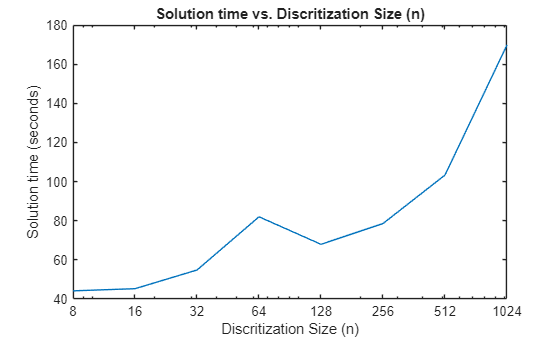


figure
semilogx(dataStack.n,dataStack.SolutionTime)
xticks(dataStack.n)
title('Solution time vs. Discritization Size (n)')
xlabel('Discritization Size (n)')
ylabel('Solution time (seconds)')

saveas(gcf,'C:\Users\Steven Watts\OneDrive - Stellenbosch University\Steven\Papers\Paper 1\Choice of Filter\nVsSolTime.png')

clearvars
insertIdx = 1;
load("C:\Users\Steven Watts\LocalMasters\Results\3_Legged.mat")
lbl = 'Y';
for idxs = 1: size(dataStack,1)
     if dataStack.Solved(idxs) && ~isempty(cell2mat(dataStack.Solution(idxs)))
        SP(insertIdx,:) = abs(squeeze( cell2mat(dataStack.Solution(idxs)).S(1,1,:,1) )');
        lbls(insertIdx) = lbl;
        insertIdx = insertIdx + 1;
    end
end

load("C:\Users\Steven Watts\LocalMasters\Results\H.mat")
lbl = 'H';
for idxs = 1: size(dataStack,1)
     if dataStack.Solved(idxs) && ~isempty(cell2mat(dataStack.Solution(idxs)))
        SP(insertIdx,:) = abs(squeeze( cell2mat(dataStack.Solution(idxs)).S(1,1,:,1) )');
        lbls(insertIdx) = lbl;
        insertIdx = insertIdx + 1;
    end
end

load("C:\Users\Steven Watts\LocalMasters\Results\Circle_Center.mat")
lbl = 'O';
for idxs = 1: size(dataStack,1)
     if dataStack.Solved(idxs) && ~isempty(cell2mat(dataStack.Solution(idxs)))
        SP(insertIdx,:) = abs(squeeze( cell2mat(dataStack.Solution(idxs)).S(1,1,:,1) )');
        lbls(insertIdx) = lbl;
        insertIdx = insertIdx + 1;
    end
end

load("C:\Users\Steven Watts\LocalMasters\Results\T.mat")
lbl = 'T';
for idxs = 1: size(dataStack,1)
     if dataStack.Solved(idxs) && ~isempty(cell2mat(dataStack.Solution(idxs)))
        SP(insertIdx,:) = abs(squeeze( cell2mat(dataStack.Solution(idxs)).S(1,1,:,1) )');
        lbls(insertIdx) = lbl;
        insertIdx = insertIdx + 1;
    end
end

load("C:\Users\Steven Watts\LocalMasters\Results\Rot_Slash_Cent.mat")
lbl = '/';
for idxs = 1: size(dataStack,1)
     if dataStack.Solved(idxs) && ~isempty(cell2mat(dataStack.Solution(idxs)))
        SP(insertIdx,:) = abs(squeeze( cell2mat(dataStack.Solution(idxs)).S(1,1,:,1) )');
        lbls(insertIdx) = lbl;
        insertIdx = insertIdx + 1;
    end
end

load("C:\Users\Steven Watts\LocalMasters\Results\Cross3.mat")
lbl = 'X';
for idxs = 1: size(dataStack,1)
     if dataStack.Solved(idxs) && ~isempty(cell2mat(dataStack.Solution(idxs)))
        SP(insertIdx,:) = abs(squeeze( cell2mat(dataStack.Solution(idxs)).S(1,1,:,1) )');
        lbls(insertIdx) = lbl;
        insertIdx = insertIdx + 1;
    end
end

lbls = lbls';
%SP = SP(:,1:4:end);

clearvars
insertIdx = 1;

fileNames = dir('C:\Users\Steven Watts\OneDrive - Stellenbosch University\Uni\Masters\Results\PaperSet');
fileNames = {fileNames.name};
fileNames = fileNames(3:end);
fileNames = fileNames(1,[7,5,3,6,4,2,1,8]);

for fileIdx = 1: length(fileNames)
    load(['C:\Users\Steven Watts\OneDrive - Stellenbosch University\Uni\Masters\Results\PaperSet\' fileNames{fileIdx}])
    lbl = fileNames{fileIdx};
    lbl = lbl(1:(end-8));
    for idxs = 1: size(dataStack,1)
         if dataStack.Solved(idxs) && ~isempty(cell2mat(dataStack.Solution(idxs)))
            SP(insertIdx,:) = abs(squeeze( cell2mat(dataStack.Solution(idxs)).S(1,1,:,1) )');
            lbls(insertIdx,1) = {lbl};
            insertIdx = insertIdx + 1;
        end
    end
end

lbls = replace(lbls,'_',' ');



%s.matlab.appearance.figure.GraphicsTheme.TemporaryValue = "light";
%set(0, 'DefaultFigureVisible', 'on')
[coeff,score,latent,tsquared,explained] = pca(SP,'NumComponents',3);


explained(1:3)

ans =    37.2548
   20.8061
    9.3053


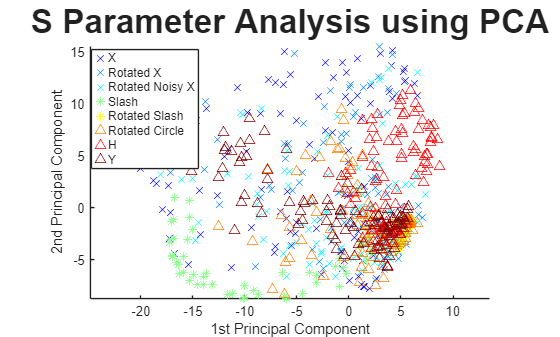


fig = figure;

hold on
gscatter(score(:,1),score(:,2),lbls,jet(8),'xxx**^^^',7)
axis equal
xlabel('1st Principal Component')
ylabel('2nd Principal Component')
title('S Parameter Analysis using PCA','FontSize', 25)

%exportgraphics(fig,'C:\Users\Steven Watts\OneDrive - Stellenbosch University\Steven\Papers\Paper 1\Data Acquisition\PCA.png')

hold off
close(gcf)

[Y, W, lambda] = LDA(score(:,1:3), lbls);

Operator '==' is not supported for operands of type 'cell'.

Error in miscPlots>LDA (line 388)
        Xj=X(L==Classes(j),:);

figure
gscatter(Y(:,1),Y(:,2), lbls)
xlabel('1st Principal Component After LDA')
ylabel('2nd Principal Component After LDA')
title('S Parameter Analysis using PCA and LDA')
saveas(gcf,'C:\Users\Steven Watts\OneDrive - Stellenbosch University\Steven\Papers\Paper 1\Data Acquisition\LDA.png')
close(gcf)

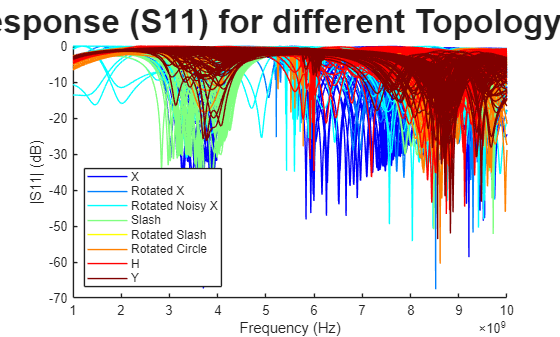

%set(0, 'DefaultFigureVisible', 'on')
figure
hold on
clrs = lbl2clr(lbls);
for idx = 1:size(SP,1)
    plot(linspace(1e9,10e9,5001), 20.*log10(SP(idx,:)),Color=clrs(idx,:),LineWidth=0.01,DisplayName=lbls{idx})
end
legend(legendUnq(),Location="southwest")
title('Electrical Response (S11) for different Topology Distributions','FontSize', 25)
xlabel('Frequency (Hz)')
ylabel('|S11| (dB)')

%saveas(gcf,'C:\Users\Steven Watts\OneDrive - Stellenbosch University\Steven\Papers\Paper 1\Data Acquisition\SP_Dense.png')
%close(gcf)

s.matlab.appearance.figure.GraphicsTheme.TemporaryValue = "light";
set(0, 'DefaultFigureVisible', 'on')
t = tiledlayout(2,1);
clrs = lbl2clr(lbls);
frqs = linspace(1e9,10e9,5001);
nexttile
hold on
for idx = size(SP,1):-1:1
    [M,I] = min(20.*log10(SP(idx,1:2500)));
    plot(frqs(I),M,'*',Color=clrs(idx,:),DisplayName=lbls(idx))

end
nexttile
hold on
for idx = size(SP,1):-1:1
    [M,I] = min(20.*log10(SP(idx,2501:5001)));
    plot(frqs(I+2500),M,'*',Color=clrs(idx,:),DisplayName=lbls(idx))

end
title(t,'Location of S11 minimum for different Topology Distributions')
xlabel(t,'Frequency (Hz)')
ylabel(t,'min(|S11|) (dB)')
legend(legendUnq(),Location="northeastoutside")

saveas(gcf,'C:\Users\Steven Watts\OneDrive - Stellenbosch University\Steven\Papers\Paper 1\Data Acquisition\S11_min.png')
close(gcf)

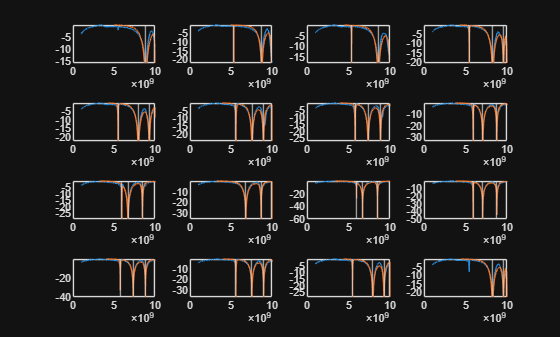

   -0.1938   -0.0137

    0.0018    0.1697    0.0371   -0.0340

   -0.0041   -0.1861    0.0000    0.0744

   -0.0068    0.1884   -0.0592   -0.0166

   -0.0105   -0.1659    0.0855   -0.0006

   -0.0169   -0.1457    0.0844   -0.0003

    0.0170   -0.1447    0.0716   -0.0002

    0.0158    0.1444   -0.0623    0.0002

   -0.0086    0.1537   -0.0387   -0.0002

    0.1702   -0.0484    0.0001

   -0.0060   -0.1526    0.0409   -0.0001

    0.0141   -0.1446   -0.0597    0.0002

    0.0150    0.1424    0.0625   -0.0002

    0.0157    0.1458    0.0747    0.0003

   -0.0092   -0.1616    0.0834    0.0005

    0.1829   -0.0643    0.0123



tfs = cell([1 size(SP,1)]);
tfc = cell([1 size(SP,1)]);

frqs = linspace(1e9,10e9,5001);
figure
tiledlayout(4,4)
for ii = 1:16%: size(SP,1)
    nexttile
    [tfs{ii},tfc{ii},cfs,bws] = fitTF(abs(SP(ii,:)));
    plot(frqs, 20*log10(abs(SP(ii,:))))
    hold on
    plot(frqs, 20*log10(abs(tfs{ii})))
    xline(cfs)
    hold off
    ylim([min(20*log10(abs(SP(ii,:)))),max(20*log10(abs(SP(ii,:))))])
    disp(bws)
end

tfs = cell([1 size(SP,1)]);
tfc = cell([1 size(SP,1)]);

frqs = linspace(1e9,10e9,5001);
for ii = 1: size(SP,1)
    [tfs{ii},tfc{ii},cfs,bws] = fitTF(abs(SP(ii,:)));
    if mod(ii,50) == 0
        disp(ii)
    end
end

    50

   100

   150

   200

   250

   300

   350

   400

   450

   500

   550

   600

   650

   700

   750

   800



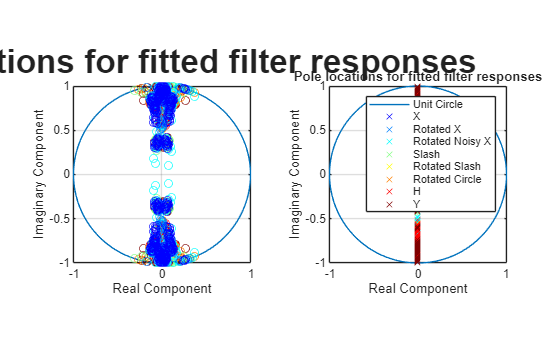

clrs = lbl2clr(lbls);

tiledlayout(1,2)
nexttile
fplot(@(t) sin(t), @(t) cos(t),DisplayName='Unit Circle');
grid on
hold on

for ii = size(SP,1):-1:1

    [b,a] = eqtflength(cell2mat(tfc{ii}.Denominator),cell2mat(tfc{ii}.Numerator));
    [z,p,k] = tf2zp(b,a);

    plot(real(z),imag(z),'o',Color=clrs(ii,:),DisplayName=lbls{ii}) 
    %plot(real(p),imag(p),'x',Color=clrs(ii,:),DisplayName=lbls(ii)) 

end

hold off
%legend(legendUnq())
xlabel('Real Component')
ylabel('Imaginary Component')
title('Zero locations for fitted filter responses','FontSize', 25)
axis equal

nexttile

fplot(@(t) sin(t), @(t) cos(t),DisplayName='Unit Circle');
grid on
hold on

for ii = 1:size(SP,1)

    [b,a] = eqtflength(cell2mat(tfc{ii}.Denominator),cell2mat(tfc{ii}.Numerator));
    [z,p,k] = tf2zp(b,a);

    %plot(real(z),imag(z),'o',Color=clrs(ii,:),DisplayName=lbls(ii)) 
    plot(real(p),imag(p),'x',Color=clrs(ii,:),DisplayName=lbls{ii}) 

end

hold off
legend(legendUnq())
axis equal
xlabel('Real Component')
ylabel('Imaginary Component')
title('Pole locations for fitted filter responses')

clear 
fileNames = dir('C:\Users\Steven Watts\OneDrive - Stellenbosch University\Uni\Masters\Results');
fileNames = {fileNames.name};
fileNames = fileNames(contains(fileNames,'.mat'))

fileNames = 1×22 cell array
    {'3_Legged.mat'}    {'Circle_Center.mat'}    {'Corner_Notch.mat'}    {'Cross2.mat'}    {'Cross21.mat'}    {'Cross3.mat'}    {'Cross4.mat'}    {'Cross5.mat'}    {'Cross5_Old.mat'}    {'Cross71.mat'}    {'Cross73.mat'}    {'Cross74.mat'}    {'Cross75.mat'}    {'Cross76.mat'}    {'Cross77.mat'}    {'H.mat'}    {'Position_Test.mat'}    {'Rot_Slash_Cent.mat'}    {'Rotation_Test.mat'}    {'T.mat'}    {'XDot.mat'}    {'patch_Sizes.mat'}


fileNames = fileNames(3:end);

fprintf('Stack Name \t \t \t # of Entries \t \t # of Solutions')

Stack Name 	 	 	 # of Entries 	 	 # of Solutions

for fileIdx = 1:length(fileNames)
    load(['C:\Users\Steven Watts\OneDrive - Stellenbosch University\Uni\Masters\Results\' fileNames{fileIdx}])
    fprintf('%s \t \t \t %d \t \t %d \n',fileNames{fileIdx},size(dataStack,1),sum([dataStack.Solved]))

end

Corner_Notch.mat 	 	 	 100 	 	 53 
Cross2.mat 	 	 	 400 	 	 399 
Cross21.mat 	 	 	 400 	 	 399 
Cross3.mat 	 	 	 400 	 	 399 
Cross4.mat 	 	 	 400 	 	 372 
Cross5.mat 	 	 	 8000 	 	 3094 
Cross5_Old.mat 	 	 	 8000 	 	 2882 
Cross71.mat 	 	 	 500 	 	 0 
Cross73.mat 	 	 	 500 	 	 498 
Cross74.mat 	 	 	 500 	 	 499 
Cross75.mat 	 	 	 500 	 	 495 
Cross76.mat 	 	 	 500 	 	 102 
Cross77.mat 	 	 	 500 	 	 0 
H.mat 	 	 	 100 	 	 28 
Position_Test.mat 	 	 	 64 	 	 19 
Rot_Slash_Cent.mat 	 	 	 100 	 	 100 
Rotation_Test.mat 	 	 	 19 	 	 19 
T.mat 	 	 	 100 	 	 0 
XDot.mat 	 	 	 100 	 	 100 
patch_Sizes.mat 	 	 	 13 	 	 0 


v=version;
rel=ver;rel=rel(1).Release;
rel=strrep(strrep(rel,'(',''),')','');
if numel(rel)==6
    year=rel(2:5);
else
    year=ver('MATLAB');year=year.Date(8:end);
end
idx=strfind(v,'Update');
if ~isempty(idx)
    idx=idx(end)+numel('Update ');
    rel=sprintf('%s_u%s',rel,v(idx:end));
end
bib_file_name=sprintf('matlab_cite_key_%s.bib',rel);
lines=cell(6,1);
lines{1}=sprintf('@manual{MATLAB:%s,',rel);
lines{2}='  address = {Natick, Massachusetts},';
lines{3}='  organization = {The Mathworks, Inc.},';
lines{4}=sprintf('  title = {{MATLAB version %s}},',v);
lines{5}=sprintf('  year = {%s},',year);
lines{6}='}';
fid=fopen(bib_file_name,'w');
for n=1:numel(lines)
    fprintf(fid,'%s\n',lines{n});
end
fclose(fid);

function [sim_tf,combined_tf,center_freqs,optimized_bw] = fitTF(measured_tf)
    % measured_tf: Frequency response of the measured transfer function
    % center_freqs: Vector of local minima (center frequencies)
    % bw_range: [min_bw, max_bw], common range for all bandwidths
    frqs = linspace(1e9,10e9,5001);
    [vlys,vlocs] = findpeaks(-mag2db(abs(measured_tf)));
    vlocs = vlocs(vlys>-(mean(mag2db(abs(measured_tf))) - std(mag2db(abs(measured_tf)))));

    center_freqs = frqs([vlocs 5001]);

    n = length(center_freqs);  % Number of filters needed
    if n == 0
        sim_tf = [];
        optimized_bw = [];
        return;
    end

    % Define the objective function (Mean Squared Error)
    objective = @(bw) compute_error(bw, center_freqs, measured_tf);

    % Set optimization options
    options = optimoptions('fminunc', 'Algorithm', 'quasi-newton', 'Display', 'none');

    % Initial bandwidth guess: Random within range
    lb = 0.01;
    ub = 0.99;
    x0 = lb + (ub - lb) * rand(1, n);

    % Run optimization
    optimized_bw = fminunc(objective, x0, options);

    [~, sim_tf, combined_tf] = compute_error(optimized_bw, center_freqs, measured_tf);


end

function [error_val, sim_tf, combined_tf] = compute_error(bw, center_freqs, measured_tf)
    % Simulate transfer function with Butterworth band-stop filters

    sim_tf = ones(size(measured_tf)); % Start with flat response
    frqs = linspace(1e9,10e9,5001);
    combined_tf = tf(1,1); % Initialize the full transfer function

    for ii = 1:length(center_freqs)
        % [b, a] = butter(1, [center_freqs(i)-bw(i)/2, center_freqs(i)+bw(i)/2] / (fs/2), 'stop');
        % sim_tf = sim_tf .* freqz(b, a, measured_tf, fs);
        [fL, fH] = extractCornerFrequencies(center_freqs(ii)./10e9, bw(ii));
        [b,a] = butter(1,[fL, fH] ,'stop','s');
        sys = tf(b,a);
        m = bode(sys,frqs./10e9);
        sim_tf = sim_tf .* squeeze(m)';

        % Multiply into the combined transfer function
        combined_tf = combined_tf * sys;
    end

    % Compute Mean Squared Error between simulated and measured TF
    error_val = mean(abs(sim_tf - measured_tf).^2);
end

function [fL, fH] = extractCornerFrequencies(fc, B)

    fL = max(roots([1 -B -fc.^2]));
    fH = fL - B;

    if fL < 0 || fH < 0
        error('Negative Frequencies')
    end
end

%
% Copyright (c) 2015, Yarpiz (www.yarpiz.com)
% All rights reserved. Please read the "license.txt" for license terms.
%
% Project Code: YPML114
% Project Title: Implementation of Linear Discriminant Analysis in MATLAB
% Publisher: Yarpiz (www.yarpiz.com)
% 
% Developer: S. Mostapha Kalami Heris (Member of Yarpiz Team)
% 
% Contact Info: sm.kalami@gmail.com, info@yarpiz.com
%
function [Y, W, lambda] = LDA(X, L)
    Classes=unique(L)';
    k=numel(Classes);
    n=zeros(k,1);
    C=cell(k,1);
    M=mean(X);
    S=cell(k,1);
    Sw=0;
    Sb=0;
    for j=1:k
        Xj=X(L==Classes{j},:);
        n(j)=size(Xj,1);
        C{j}=mean(Xj);
        S{j}=0;
        for i=1:n(j)
            S{j}=S{j}+(Xj(i,:)-C{j})'*(Xj(i,:)-C{j});
        end
        Sw=Sw+S{j};
        Sb=Sb+n(j)*(C{j}-M)'*(C{j}-M);
    end
    [W, LAMBDA]=eig(Sb,Sw);
    lambda=diag(LAMBDA);
    [lambda, SortOrder]=sort(lambda,'descend');
    W=W(:,SortOrder);
    Y=X*W;
end

function unqLegHands = legendUnq(h, sortType)
% unqLegHands = legendUnq(h, sortType)
%   Run this function just before running 'legend()' to avoid representing duplicate or missing
% DisplayNames within the legend. This solves the problem of having a cluttered legend with 
% duplicate or generic values such as "data1" assigned by matalab's legend() function.  This 
% also makes is incredibly easy to assign one legend to a figure with multiple subplots. 
% Use the 'DisplayName' property in your plots and input the axis handle or the figure handle 
% so this code can search for all potential legend elements, find duplicate DisplayName strings, 
% and remove redundent components by setting their IconDisplayStyle to 'off'.  Then call 
% legend(unqLegHands) to display unique legend components. 
% INTPUT
%       h: (optional) either a handle to a figure, an axis, or a vector of axis handles. The code 
%           will search for plot elements in all axes belonging to h.  If h is missing, gca is used.
%       sort: (optional) can be one of the following strings that will sort the unqLeghands.
%           'alpha': alphabetical order. 
% OUTPUT
%       unqLegHands: a list of handles that have unique DisplayNames; class 'matlab.graphics.chart.primitive.Line'.
%           ie: unqLegHands = legendUnq(figHandle); legend(unqLegHands)
% EXAMPLE 1: 
%         figure; axis; hold on
%         for i=1:10
%             plot(i,rand(), 'ko', 'DisplayName', 'randVal1');        % included in legend
%             plot(i+.33, rand(), 'ro', 'DisplayName', 'randVal2');   % included in legend       
%         end
%         plot(rand(1,10), 'b-'); 	% no DisplayName so it is absent from legend
%         legend(legendUnq())
% EXAMPLE 2: 
%         fh = figure; subplot(2,2,1); hold on
%         plot(1:10, rand(1,10), 'b-o', 'DisplayName', 'plot1 val1')
%         plot(1:2:10, rand(1,5), 'r-*', 'DisplayName', 'plot1 val2')
%         subplot(2,2,2); hold on
%         plot(1:10, rand(1,10), 'm-o', 'DisplayName', 'plot2 val1')
%         plot(1:2:10, rand(1,5), 'g-*', 'DisplayName', 'plot2 val2')
%         subplot(2,2,3); hold on
%         plot(1:10, rand(1,10), 'c-o', 'DisplayName', 'plot3 val1')
%         plot(1:2:10, rand(1,5), 'k-*', 'DisplayName', 'plot3 val2')
%         lh = legend(legendUnq(fh)); 
%         lh.Position = [.6 .2 .17 .21];
%
% Danz 180515
% Change history
% 180912 fixed error when plot is empty
% 180913 adapted use of undocumented function for matlab 2018b
persistent useOldMethod
% If handle isn't specified, choose current axes
if nargin == 0
    h = gca; 
end
% If user entered a figure handle, replace with a list of children axes; preserve order of axes
if strcmp(get(h, 'type'), 'figure')
    h = flipud(findall(h, 'type', 'Axes')); 
end
% set flag to use old method of obtaining legend children
% In 2018b matlab changed an undocumented function that obtains legend handles. 
useOldMethod = verLessThan('matlab', '9.5.0'); 
% Set the correct undocumented function 
if useOldMethod
    getLegendChildren = @(x) graph2dhelper('get_legendable_children', x);
else
    getLegendChildren = @(x) matlab.graphics.illustration.internal.getLegendableChildren(x);
end
% Get all objects that will be assigned to legend.
% This uses an undocumented function that the legend() func uses to get legend componenets.
legChildren = matlab.graphics.chart.primitive.Line; %initializing class (unsure of a better way)
for i = 1:length(h)
    temp = getLegendChildren(h(i));
    if ~isempty(temp)
        legChildren(end+1:end+length(temp),1) = temp; 
    end
end
legChildren(1) = [];
% Get display names
dispNames = get(legChildren, 'DisplayName');
if isempty(dispNames)
    dispNames = {''}; 
end
if ~iscell(dispNames)
    dispNames = {dispNames}; 
end
% Find the first occurance of each name 
[~, firstIdx] = unique(dispNames, 'first'); 
% Create an index of legend items that will be hidden from legend
legRmIdx = true(size(legChildren)); 
legRmIdx(firstIdx) = false; 
% Add any elements that have no displayName to removal index (legend would assign them 'dataX')
legRmIdx = legRmIdx | cellfun(@isempty,dispNames);
% get all annotations
annot = get(legChildren, 'Annotation'); 
% Loop through all items to be hidden and turn off IconDisplayStyle
for i = 1:length(annot)
    if legRmIdx(i)
        set(get(annot{i}, 'LegendInformation'), 'IconDisplayStyle', 'off');
    end
end
% Output remaining, handles to unique legend entries
unqLegHands = legChildren(~legRmIdx); 
% Sort, if user requested
if nargin > 1 && ~isempty(sortType) && length(unqLegHands)>1
    [~, sortIdx] = sort(get(unqLegHands, 'DisplayName'));
    unqLegHands = unqLegHands(sortIdx); 
end
end

function colors =  lbl2clr(labels)
    % Get unique labels
    uniqueLabels = unique(labels);
    uniqueLabels = uniqueLabels([7,5,3,6,4,2,1,8]);
    
    % Generate a colormap with as many colors as there are labels
    cmap = jet(length(uniqueLabels)); % or use 'jet', 'parula', etc.
    
    % Create a color matrix where each row corresponds to a point's color
    colors = zeros(length(labels), 3);
    for ii = 1:length(uniqueLabels)
        idx = matches(labels,uniqueLabels{ii}); % Find all points with this label
        colors(idx, :) = repmat(cmap(ii, :), sum(idx), 1);
    end
end